%Kalman Filter
H=[ %Measurement matrix for the filter. Converts units.
    1/9.8,    0,    0,     0,     0,     0;
        0,1/9.8,    0,     0,     0,     0;
        0,    0,1/9.8,     0,     0,     0;
        0,    0,    0,180/pi,     0,     0;
        0,    0,    0,     0,180/pi,     0;
        0,    0,    0,     0,     0,180/pi;
    ];
R=[ %Covariance matrix. Data was obtained from the MPU6050 datasheet
       0.01,0.02,0.02,0.00,0.00,0.00;
       0.02,0.01,0.02,0.00,0.00,0.00;
       0.02,0.02,0.01,0.00,0.00,0.00;
       0.10,0.10,0.10,0.45,0.00,0.00;
       0.10,0.10,0.10,0.00,0.45,0.00;
       0.10,0.10,0.10,0.00,0.00,0.45;
    ]; 
% Note that the covariance matrix is not self-adjoint, this
% is to prevent gyroscope measurements from affecting accelerometer
% measurements. During testing it was determined the contribution
% is neglibile.
w=[0;0;1]; % This unit vector represents the normal to the cup's bottom
Q=R;
Sk=eye(3);
xk=[0;0;9.8;0;0;0];
pk=ones(6);
for i = 1:3000 %A 3s initialization period to allow the simulation to settle
    dt=.001;
    [xk,pk] = predict(xk,pk,Q);
    [xk,pk] = update(xk,pk,[0;0;1;0;0;0],H,R);%simulated 1g normal force
    Sk=Sz(xk(6)*dt)*Sy(xk(5)*dt)*Sx(xk(4)*dt)*Sk;
end
% Variable initalization
cup=[0;0;0;0;0;0;0;0;0;0;0;1];
liq=[0;0;1;0;0;0;0;0;0];
contact=false; %used to debug points where the liq would make or break contact
lastcontact=true;
processeddata=cup'; %Recording of simulation output
% realdata is in the form:
%  [x acc;y acc;z acc;x gyro;y gyro;z gyro;elapsed time in microseconds]
for i= 2:1180
    dt=(realdata{i,7}-realdata{(i-1),7})*1e-6; 
    %predict kalman state
    [xk,pk] = predict(xk,pk,Q);
    %perform kalman correction
    [xk,pk] = update(xk,pk,[realdata{i,1};realdata{i,2};realdata{i,3};realdata{i,4};realdata{i,5};realdata{i,6}],H,R);
    %rotate the rotation matrix
    Sk=Sz(xk(6)*dt)*Sy(xk(5)*dt)*Sx(xk(4)*dt)*Sk;
    %update simulation
    [cup,liq,target] = updateAll(cup,liq,w,xk,Sk,dt);
    processeddata=[processeddata;cup'];
    if ~incontact(liq,cup)
        contact=false;
        [x,y] = rotateToTarget(w,target);
        w=rotatecup(w,Sz(0)*Sx(x*pi/180)*Sy(y*pi/180));
    else
        contact=true;
    end
    if (lastcontact~=contact) %Ouput contact information
        contact
        i
        dt
        target
        updateliq(liq,cup,0.0001)
        cup(1:9)
        cup(10:12)
        lastcontact=contact;
    end
end

contact = logical
   0


i = 2

dt = 0.0084

target =      0
     0
    -1


ans =          0
         0
    0.9996
         0
         0
   -0.0838
         0
         0
   -9.8000


ans =    -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0003
   -0.0001
   -0.0092
   -0.0380
   -0.0095


ans =     0.0000
    0.0000
    1.0000


contact = logical
   1


i = 77

dt = 0.0085

target =      0
     0
    -1


ans =    -0.0052
   -0.0559
   -1.0012
   -0.0180
   -0.1944
   -0.0003
   -0.0414
   -0.3573
    0.0034


ans =    -0.0052
   -0.0558
   -0.0012
   -0.0180
   -0.1943
   -0.0003
   -0.0414
   -0.3573
    0.0034


ans =     0.0000
    0.0000
    1.0000


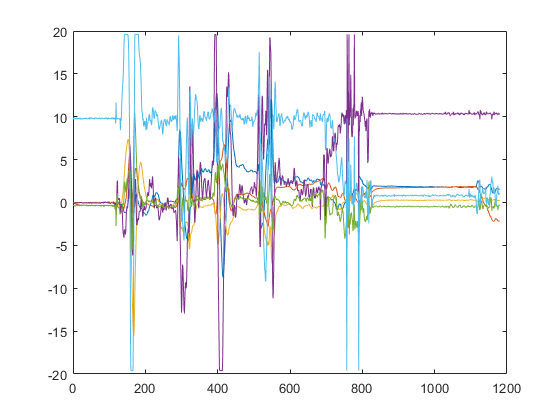

plot(1:1180,processeddata(1:1180,7:9),1:1180,realdata{1:1180,1:3}*9.8)

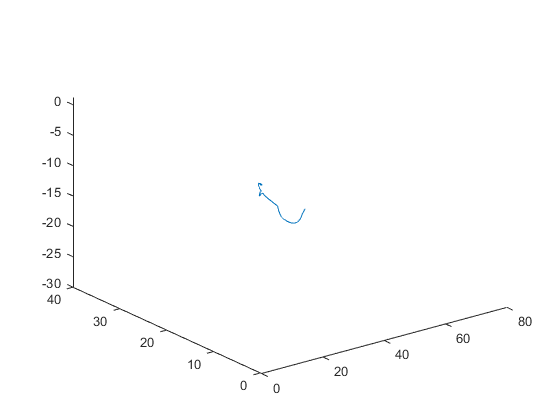

plot3(processeddata(1:1180,1)+processeddata(1:1180,10),processeddata(1:1180,2)+processeddata(1:1180,11),processeddata(1:1180,3)+processeddata(1:1180,12))

function [cup_o,liq_o,target] = updateAll(cup_i,liq_i,w,xk,Sk,dt)
    %Performs all simualtion update matters by calling sub function
    cup_o = updatecup(cup_i,w,xk,Sk,dt);
    liq_o = updateliq(liq_i,cup_i,dt);
    target = w;
    if ~incontact(liq_i,cup_i)
        target = predictLiqExit(liq_i,cup_i);
    end
end
function [xk,pk] = predict(xk,pk,Q) %Kalman prediction
    xk = F()*xk;
    pk = F()*pk*F()'+Q;
end
function [xk,pk] = update(xk,pk,z,H,R) %kalman update
    yk=z-H*xk;
    Kk=pk*H'*(R+H*pk*H')^-1;
    xk=xk+Kk*yk;
    pk=(eye(6)-Kk*H)*pk;
end
function output = F() %Determine kalman state transition matrix
    output = eye(6);
end
function output = Sx(tx)
    output=[1,0,0;0,cos(tx),-sin(tx);0,sin(tx),cos(tx)];
end
function output = Sy(ty)
    output=[cos(ty),0,sin(ty);0,1,0;-sin(ty),0,cos(ty)];
end
function output = Sz(tz)
    output=[cos(tz),-sin(tz),0;sin(tz),cos(tz),0;0,0,1];
end
function plotRange(xk,pk)
    xkmax=xk+pk*[1;1;1;1;1;1];
    xkmin=xk-pk*[1;1;1;1;1;1];
    plot(1:6,xkmax(1:6,1),'-^',1:6,xkmin(1:6,1),'-v',1:6,xk,'-o')
end
function output = updatecup(cup_i,w,xk,Sk,dt)
    % Updates the state of the cup based on the local acceleration
    % rotated into the global coordinate system.
    Gacc = Sk*xk(1:3)+[0;0;-9.8];
    output = cup_i;
    output = [output(1:6);Gacc;Sk*w];
    output = [
        1,0,0,  dt,0,0, dt^2/2,0,0,  0,0,0;
        0,1,0,  0,dt,0, 0,dt^2/2,0,  0,0,0;
        0,0,1,  0,0,dt, 0,0,dt^2/2,  0,0,0;
        0,0,0,  1,0,0,  dt,0,0,      0,0,0;
        0,0,0,  0,1,0,  0,dt,0,      0,0,0;
        0,0,0,  0,0,1,  0,0,dt,      0,0,0;
        0,0,0,  0,0,0,  1,0,0,       0,0,0;
        0,0,0,  0,0,0,  0,1,0,       0,0,0;
        0,0,0,  0,0,0,  0,0,1,       0,0,0;
        0,0,0,  0,0,0,  0,0,0,       1,0,0;
        0,0,0,  0,0,0,  0,0,0,       0,1,0;
        0,0,0,  0,0,0,  0,0,0,       0,0,1;
        ]*output;
end
function output = updateliq(liq_i,cup_i,dt)
    output = liq_i;
    if ~incontact(liq_i,cup_i)
        %if cup is not in contact it is in free-fall
        output(7:9)=[0;0;-9.8];
    else
        %otherwise its position is that of the cup
        output(1:3)=cup_i(1:3)-cup_i(10:12);
        % Its velocity is >= that of the cup in the direction of the
        % opening
        output(4:6)=max(dot(cup_i(4:6),cup_i(10:12)),dot(output(4:6),cup_i(10:12)))*cup_i(10:12);
        output(4:6)=output(4:6)+cup_i(4:6)-dot(cup_i(4:6),cup_i(10:12))*cup_i(10:12);
        % Its acceleration is >= that of the cup in the direction of the
        % opening
        output(7:9)=max(dot(cup_i(7:9),cup_i(10:12)),dot(cup_i(10:12),[0;0;-9.8]))*cup_i(10:12);
        output(7:9)=output(7:9)+cup_i(7:9)-dot(cup_i(7:9),cup_i(10:12))*cup_i(10:12);
    end
    output = [
        1,0,0,  dt,0,0, dt^2/2,0,0;
        0,1,0,  0,dt,0, 0,dt^2/2,0;
        0,0,1,  0,0,dt, 0,0,dt^2/2;
        0,0,0,  1,0,0,  dt,0,0;
        0,0,0,  0,1,0,  0,dt,0;
        0,0,0,  0,0,1,  0,0,dt;
        0,0,0,  0,0,0,  1,0,0;
        0,0,0,  0,0,0,  0,1,0;
        0,0,0,  0,0,0,  0,0,1;
        ]*output;
end
function output = incontact(liq_i,cup_i)
    bottom_position=cup_i(1:3)-cup_i(10:12);
    pos_diff=liq_i(1:3)-bottom_position;
    % Define vector orthogonal to the bottom plane of the cup
    orth_bottom=dot(pos_diff,cup_i(10:12))*cup_i(10:12);
    non_orth_bottom=pos_diff-orth_bottom;
    % If it is within 1.5cm perpendicular to the bottom and 10cm parallel
    % to the bottom, it is in contact.
    if norm(non_orth_bottom)>0.1 || norm(orth_bottom)>0.015
        output = false;
    else 
        output = true;
    end
end
function output = rotatecup(w,Sk)
    output = Sk*w;
end
function [theta_x,theta_y] = rotateToTarget(w_i,target_i)
    w_i=-w_i;
    if norm(w_i-target_i)>.05
        a=w_i(3);
        b=w_i(1);
        c=target_i(1);
        syms x;
        theta_y=mod(360-acosd(c/(a^2+b^2)^.5)+double(limit(atand(a/x),x,b,'left')),360);
        a=w_i(2);
        b=-w_i(1)*sind(theta_y)+w_i(3)*cosd(theta_y);
        c=target_i(3);
        theta_x=mod(360-acosd(c/(a^2+b^2)^.5)+double(limit(atand(a/x),x,b,'left')),360);
    else
        theta_y=0;
        theta_x=0;
    end        
end
function output = predictLiqExit(liq_i,cup_i)
    new_liq = updateliq(liq_i,cup_i,3);
    if norm(new_liq(1:3))<1.5 %if liq does not exit in 3s, don't worry
        output=[0;0;0];
    else
        new_liq = liq_i;
        while norm(new_liq(1:3))<1.1 && ~incontact(new_liq,cup_i)
            new_liq = updateliq(new_liq,cup_i,0.01);
        end
        output = (new_liq(1:3)/norm(new_liq(1:3)));
    end
    
end
